# Harder than it Looks: An Attempt to Model an Ultrasound Wave

[⇦ Main Menu](matlab:open('MainMenu.mlx'))

Ultrasound imaging, also known as sonography, uses high-frequency sound waves to create images of the inside of the body. The process involves sending sound waves into the body and then detecting the echoes that return from the boundaries between different tissues. To be able to build a detector that will capture the images, it would be helpful to create a mathematical model to test with. 

[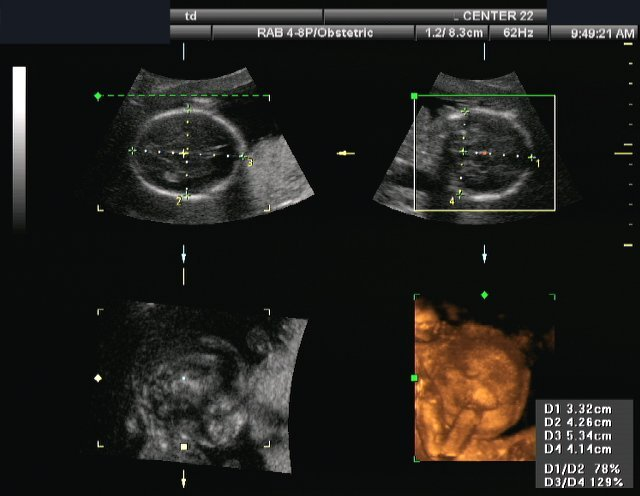](https://en.wikipedia.org/w/index.php?curid=19500021)

Credit: Terry J. DuBose, M.S., RDMS CC BY-SA 3.0, [https://en.wikipedia.org/w/index.php?curid=19500021](https://en.wikipedia.org/w/index.php?curid=19500021)

In the context of imaging a fetus, the model must account for the propagation of sound waves through various tissues and their reflection at the interfaces between those tissues, such as the amniotic fluid and fetal tissues.

**Before you get started:**

This live script is intended to be used with the code visible and output inline. On the **View** tab of the MATLAB Toolstrip, in the **View** section, select **Output Inline**. Alternately, select **Output Inline **using the icon   at the top right of the Live Editor pane.

 Interacting with this live script will help you become familiar with MATLAB as concepts and commands are introduced together. If you need more instruction, consider taking [MATLAB Onramp](https://matlabacademy.mathworks.com/details/matlab-onramp/gettingstarted), a free two-hour online tutorial that teaches the essentials of MATLAB.

   For an optimal experience, follow the instructions and steps in the given sequence. Proceed to a new section only after completing the preceding one. Some sections depend on variables created in prior sections and they will generate errors if run out of order.

## Fetal Imaging

An ultrasound transducer sends a pulse of sound waves into the body to image a fetus. When these waves encounter interfaces (e.g., between amniotic fluid and fetal tissue), echoes are generated and returned to the transducer. These echoes' time delay and intensity are used to construct an image.

- **Calculating Distance**: The distance to an interface can be calculated using the time delay of the echo, allowing the construction of a two-dimensional image slice by slice.

- **Constructing the Image**: The intensity of the echoes, which depends on the reflection coefficient at each interface, helps to differentiate between various tissues, fluids, and structures within the body.

The wave equation can describe the propagation of a sound wave as a second-order wave equation with damping:


$${\nabla^2 p(x, t) - \frac{1}{c^2} \frac{\partial^2 p(x, t)}{\partial t^2} + \alpha\frac{\partial p(x,t)}{\partial t}= 0}$$
   
$$(\star)$$


where:

- $p(x, t)$ is the pressure at position $x$ and time $t$,

- $\nabla^2 = \left(\frac{\partial^2}{\partial x^2} +\frac{\partial^2}{\partial y^2} + \frac{\partial^2}{\partial z^2}\right)$ is the Laplacian operator, indicating how the pressure varies in space,

- $c$ is the speed of sound in the medium,

- $\alpha$ is the damping coefficient.

### Simplified Ultrasound Model

Consider an ultrasound wave emanating from the transducer. 

#### Assumptions

1. **Homogeneous Medium**: Assume the body is a homogeneous medium of two types: soft tissue and amniotic fluid, even though, in reality, it consists of various tissues with different acoustic properties.

2. **Straight-Line Propagation**: Sound waves propagate in straight lines without scattering.

3. **Constant Speed of Sound**: The speed of sound in soft tissue is constant at approximately $1540 \text{ m}/\text{s}$. The speed of sound in amniotic fluid is constant at approximately $1510 \text{ m}/\text{s}$.

4. **Reflections**: According to the impedance calculations, reflections occur perfectly at interfaces between different types of tissues.

5. **Density**: The density of soft tissue will be assumed to be $1050 \text{ kg}/\text{m}^3$ and the density of amniotic fluid will be assumed to be $1000 \text{ kg}/\text{m}^3$.

### Echo Detection

The time delay, $\Delta t$, between the transmitted and received echoes is related to the distance, $d$, to the reflecting interface, and the speed, $c$ at which the wave is propagated:

${\Delta t = \frac{2d}{c}}$.

**Exercise 1: **Assume that there is a first echo from the soft-tissue/amniotic fluid boundary at a distance `L1`, that arrives in 13 $\mu s$, and a second echo from the amniotic fluid/soft-tissue boundary at a distance `FetalDistance`, that arrives in 45 $\mu s$. How far away is the soft-tissue/amniotic fluid boundary? How far away is the fetus from the transducer? Please give your answers in centimeters.

% Complete your computations here
% Update the values of L1 and FetalDistance with your results

L1 = 0;                     % cm
FetalDistance = 0;          % cm
disp("The fetus is " + FetalDistance + " cm from the transducer.")
CheckExercise1(L1,FetalDistance)

Excellent, we have calculated the distance to the fetus. We're done, right? Not quite yet. Where does this echo come from?

### Reflection and Transmission

In ultrasound imaging, the acoustic impedance of a medium is a critical parameter that determines how much of the ultrasound wave is reflected at the boundary between two different materials. The acoustic impedance $Z$ is given by the product of the medium's density $\rho $ and the speed of sound $c$ in that medium:


$$Z=\rho c$$


The acoustic impedance is measured in Rayls, $\frac{\text{kg}}{\text{m}^2\cdot s}$, in the SI system.

When a sound wave encounters an interface between two different tissues, part of the wave is reflected towards the transducer. The intensity of the reflected wave, $I_r$, can be related to the incident wave, $I_i$, by the reflection coefficient, $R$, at the interface:


$${I_r = R^2 \cdot I_i}$$


The reflection, $R$, and transmission, $\tau$, coefficients depend on the acoustic impedances of the two media:

$R = \frac{Z_{\text{in}} - Z_{\text{out}}}{Z_{\text{in}} + Z_{\text{out}}}$     and     $\tau = \frac{2Z_{\text{in}}}{Z_{\text{in}}+Z_{\text{out}}}$

where:

$Z_{\text{in}}$ and $Z_{\text{out}}$ are the acoustic impedances of the two media.

**Exercise 2: **Using the assumptions on speed and density, calculate $Z_{\text{soft tissue}}$ and $Z_{\text{amniotic fluid}}$. Then, calculate the reflection and transmission coefficients for the soft tissue (mother) to the amniotic fluid boundary, $R_1$ and $\tau_1$, and the amniotic fluid to soft tissue (fetus) boundary, $R_2$ and $\tau_2$.

c_SoftTissue = 1540;       % m/s
c_AmnioticFluid = 1510;    % m/s
rho_SoftTissue = 1050;     % kg/m^3
rho_AmnioticFluid = 1000;  % kg/m^3

% Compute the values for Z, R, and tau
Z_SoftTissue = 0
Z_AmnioticFluid = 0

R_1 = 0
tau_1 = 0
R_2 = 0
tau_2 = 0
CheckExercise2(Z_AmnioticFluid,Z_SoftTissue,R_1,tau_1,R_2,tau_2)

This simplified model abstracts many complexities of ultrasound physics and human anatomy but provides a basis for understanding how ultrasound imaging works. Advanced models would incorporate more detailed acoustic properties of tissues, non-linear propagation, scattering, and variable attenuation to improve image accuracy and detail. 

Now that we've simplified the model and defined several parameters, we're ready to solve the problem, right?

**Exercise 3: **Which of the following are necessary to implement a finite difference solution to Equation $(\star)$ on the interval $[0,L]$ where $L$ = `FetalDistance`? 

Discretize = false; % Discretize the domain
ApproximatePDE = false; % Approximate the partial differential equation, such as with finite differences
IC0 = false; % Define an initial condition for p(x,0) = f(x)
IC1 = false; % Define an initial condition for the first derivative dp/dt(x,0) = g(x)
IC2 = false; % Define an initial condition for the second derivative d^2p/dt^2(x,0) = h(x)
BC1 = false; % Define a boundary condition for p(0,t) = BC1(t)
BC2 = false; % Define a boundary condition for p(L,t) = BC2(t)

 
CheckExercise3(Discretize,ApproximatePDE,IC0,IC1,IC2,BC1,BC2)

## Approximate a Solution

As with most analyses, we shall begin by simplifying the model even further, and then we will look at how to improve the fidelity. Let's start with the second-order wave equation in one dimension and a continuous approximation of the wave speed:


$$\frac{\partial^2 p}{\partial x^2}-\frac{1}{c^2}\frac{\partial^2p}{\partial t^2} = 0$$
                
$$(\heartsuit)$$


### Analytic Solution

Notice that this wave equation $(\heartsuit)$ is linear and separable when $c$ is constant:

$\left(\frac{\partial}{\partial t}+c\frac{\partial}{\partial x}\right)\left(\frac{\partial}{\partial t}-c\frac{\partial}{\partial x}\right) p = 0$,

Therefore, for a constant $c$, we can expect that the solution will be a sum of a wave traveling right at speed $c$ and a wave traveling left at speed $c$. In this case, where $c$ is not constant, there will be additional complications. 

Let's define $c(x) = \begin{cases}1540 & x < L_1 \\ 1510 & x \geq L_1\end{cases} \approx 780+15\tanh(100(x-L_1))$, where $L_1$ is the soft-tissue/amniotic fluid boundary point.

### Initial Conditions

We can define an initial condition of $p(x,0) = 0$ and an initial velocity of $\frac{\partial p(x,0)}{\partial t} = 0$. 

### Boundary Conditions

We also need to define boundary conditions for Equation $(\heartsuit)$. Let's set $p(0,t) = \begin{cases} 1 & 0 < t < 0.1 \mu\text{s} \\ 0 & \text{otherwise} \end{cases}$ to represent an ultrasound wave pulse impinging on the system from the left boundary that is switched on at $t=0$. We also need a boundary condition at the right boundary. We'll assume a homogeneous Neumann boundary condition at $L$ to start: $\frac{\partial p(L,t)}{\partial x} = 0$. 

## Approximate the Wave Equation

Use the method of finite differences to solve Equation $(\heartsuit)$ as presented above:


$$u_{i,j+1} = \frac{c^2\Delta t^2}{\Delta x^2}u_{i+1,j} + \left(2-2\frac{c^2\Delta t^2}{\Delta x^2}\right)u_{i,j}+ \frac{c^2\Delta t^2}{\Delta x^2}u_{i-1,j} -u_{i,j-1}$$


% Parameters
L = FetalDistance;  % cm
N = 201; % Number of spatial points
M = 900; % Number of time steps
WaveOffTime = 0.1; % End of initial pulse (us)
c1 = c_SoftTissue/100; % Speed of sound in tissue (cm/us)
c2 = c_AmnioticFluid/100; % Speed of sound in amniotic fluid (cm/us)
X = linspace(0,L,N);
c = (c1+c2)/2+(c1-c2)/2*tanh(100*(X-L1));
dx = L/(N-1);
dt = dx/(2*max(c1,c2)); % Time step in microseconds per CFL condition

% Initialize the wave
u = zeros(N,M);

% Iterate over time
OffDiag = c.^2*dt^2/dx^2;
MainDiag = 2-2*c.^2*dt^2/dx^2;

UpdateRule = diag(MainDiag,0)+ diag(OffDiag(2:end),-1) + diag(OffDiag(1:end-1),1);

Notice that this `UpdateRule` involves only information about the previous time step, but the complete approximation scheme involves $u_{i,j-1}$ as well at the three points $u_{i+1,j}, u_{i,j},$ and $u_{i-1,j}$. This requires taking one time step using a different approximation scheme to start our computation. 


$$\frac{\partial p(x,0)}{\partial t} = 0 \Rightarrow \frac{p(x,\Delta t)-p(x,0)}{\Delta t} +\mathcal{O}(\Delta t) =  0$$



$$p(x,\Delta t) \approx  \Delta t\cdot c0+ p(x,0) = 0$$


% Initial Boundary Condition information
u(:,2) = 0;

for jTimestep = 2:M-1
    uNext = UpdateRule*u(:,jTimestep)-u(:,jTimestep-1);
    u(2:end-1,jTimestep+1) = uNext(2:end-1);

    A centered difference approximation to the Neumann boundary condition says:


$$\frac{\partial p(L,t)}{\partial x} = 0 = \frac{p(L+\Delta x,t)-p(L-\Delta x,t)}{2\Delta x} + \mathcal{O}(\Delta x^2)$$



$$p(L+\Delta x,t) = p(L-\Delta x,t)+\mathcal{O}(\Delta x^2)$$



$$u_{M+1,j} \approx u_{M-1,j}$$
                

    if jTimestep*dt < WaveOffTime
        u(1,jTimestep+1)=1;    % Dirichelet
        u(end,jTimestep+1) = u(end-1,jTimestep+1); % Neumann
    else
        u(1,jTimestep+1) = 0;  % Dirichelet
        u(end,jTimestep+1) = u(end-1,jTimestep+1); % Neumann
    end
end

% Visualization
p = plot(X(2:end-1),u(2:end-1,1));
ylim([min(u,[],"all") max(u,[],"all")])
xline(L1,SeriesIndex=2)
xlabel('Spatial Position (cm)');
ylabel('Amplitude');
title('1D Wave Equation');
for jTimestep = 2:M
    p.YData = u(2:end-1,jTimestep);
    drawnow
end

 **Reflect**. Are you satisfied with this numerical solution?

Satisfied = "I don't know";
CheckExercise4(Satisfied)

 **Reflect**.

- What happens if you change the coefficient in the hyperbolic tangent? Or replace it with a step function?

- What changes do you need to make to the implementation above to numerically approximate Equation $(\star)$ rather than Equation $(\heartsuit)$?

- How can you approach mathematically modeling the physics of impedance matching, as discussed in Reflection and Transmission?

- Do you have any concerns about moving from a 1D to a 2D or 3D spatial model? 

- Is there anything you can do to minimize the impact of the [Gibbs phenomenon](https://en.wikipedia.org/wiki/Gibbs_phenomenon) on your solution?

## Further Exploration

There are many more challenges to address when building a useful mathematical model of an ultrasound. You might want to start by exploring one or more of these ideas:

- [Various types of boundary conditions](https://en.wikipedia.org/wiki/Boundary_conditions_in_fluid_dynamics)

- [Inverse problems](https://en.wikipedia.org/wiki/Inverse_problem)

[⇦ Return to the main menu](matlab:open('MainMenu.mlx'))

function CheckExercise1(L1Boundary,FetalDistance)
arguments
    L1Boundary (1,1) double {mustBeNonnegative}
    FetalDistance (1,1) double {mustBeNonnegative}
end

c_SoftTissue = 1540;     % m/s
c_AmnioticFluid = 1510;  % m/s
dt1 = 13*10^(-6);        % s
dt2 = 45*10^(-6);        % s
L1 = c_SoftTissue*dt1/2*100;           % cm
L2 = c_AmnioticFluid*(dt2-dt1)/2*100;  % cm
FD = L1+L2;              % cm
flag = 0;

if L1Boundary == L1
    disp("You have the correct value of L1.")
elseif L1Boundary == 0
    disp("This is the default value of L1.")
else
    disp("You have the incorrect value of L1.")
end

if FetalDistance == 0
    disp("This is the default value." + newline + ...
        "Please update the value of FetalDistance with your computed result.")
    flag = -1;
elseif abs(FetalDistance-FD)<0.1
    disp("Yes, that is the fetal distance in cm.")
    flag = 1;
elseif abs(FetalDistance-2*FD)<0.1
    disp("Did you forget the wave path is there and back?" + newline + "What is the length to travel?")
elseif abs(FetalDistance-FD*10^6)<1e5
    disp("You need to express the time in seconds.")
elseif abs(FetalDistance-2*FD*10^6)<1e5
    disp("Did you forget the wave path is there and back?" + newline + "What is the length to travel?" + newline ...
        + "Also, you need to express the time in seconds.")
elseif abs(FetalDistance-FD*100)<10
    disp("You need to express your answer in centimeters.")
elseif abs(FetalDistance-2*FD*100)<10
    disp("Did you forget the wave path is there and back?" + newline + "What is the length to travel?" + newline ...
        +"Also, you need to express your answer in centimeters.")
else
    disp("That is incorrect. Please check your speeds and times.")
end

if flag == 0
    disp("Please try again.")
end
end

function CheckExercise2(Z_Amnio,Z_Soft,R_1,tau_1,R_2,tau_2)
if all([Z_Amnio Z_Soft R_1 tau_1 R_2 tau_2] == 0)
    disp("These are the default values for Z, R, and tau." + newline + ...
        "Please compute the values and submit them for checking.")
else
c_SoftTissue = 1540;       % m/s
c_AmnioticFluid = 1510;    % m/s
rho_SoftTissue = 1050;     % kg/m^3
rho_AmnioticFluid = 1000;  % kg/m^3

Z_ST = rho_SoftTissue*c_SoftTissue;
Z_AF = rho_AmnioticFluid*c_AmnioticFluid;

R_1Sol = (Z_AF-Z_ST)/(Z_AF+Z_ST);
tau_1Sol = 2*Z_ST/(Z_AF+Z_ST);
R_2Sol = (Z_ST-Z_AF)/(Z_AF+Z_ST);
tau_2Sol = 2*Z_AF/(Z_AF+Z_ST);

Ex2Feedback("acoustic impedance of soft tissue",Z_ST,Z_Soft,UnitStr=" kg/m^2/s")
Ex2Feedback("acoustic impedance of amniotic fluid",Z_AF,Z_Amnio,UnitStr=" kg/m^2/s")
Ex2Feedback("reflectance R_1",R_1Sol,R_1)
Ex2Feedback("transmittance tau_1",tau_1Sol,tau_1)
Ex2Feedback("reflectance R_2",R_2Sol,R_2)
Ex2Feedback("transmittance tau_2",tau_2Sol,tau_2)
end
end

function Ex2Feedback(str,sv,av,opt)
arguments
    str (1,1) string
    sv (1,1) double
    av (1,1) double
    opt.UnitStr (1,1) string = "" 
end
if abs((sv-av)/sv) < 0.01
    disp("Yes, the " + str + " is " + sv + opt.UnitStr + ".")
elseif av == 0
    disp("This is the default value for " + str + "." + newline + ...
        "Please try again.")
else
    disp("No, the " + str + " is not " + av + opt.UnitStr + "." + ...
        "Please try again.")
end
end

function CheckExercise3(Discretize,ApproximatePDE,IC0,IC1,IC2,BC1,BC2)
SolnVec = [Discretize ApproximatePDE IC0 IC1 IC2 BC1 BC2];
AnsVec = [1 1 1 1 0 1 1];
if all(AnsVec==SolnVec)
    disp("Exercise 3 is correct.")
    disp("The discretization is necessary to work numerically.")
    disp("The finite difference approximations to the derivatives are in the method name.")
    disp("The initial value is required to start the method.")
    disp("The initial derivative is required to start the method.")
    disp("The x=0 boundary value defines the left endpoint.")
    disp("The x=L boundary value defines the right endpoint.")
    disp("Some information about how the solutions mix at the internal boundary is also required.")
elseif all(SolnVec == 0)
    disp("These are the default values." + newline + ...
        "Which of these are necessary to solve the problem?")
else
    WrongVals = SolnVec~=AnsVec;
    disp("You have " + sum(WrongVals) + " selections wrong." + newline + ...
        "Please try again.")
end
end

function CheckExercise4(str)
arguments
    str (1,1) string {mustBeMember(str,["yes" "no" "I don't know"])}
end

switch str
    case "yes"
        disp("That is a bit concerning. What is the impact of the change in tissue type?" + newline + ...
            "Shouldn't the wave be reflecting as well as transmitting at the interface?" + newline + ...
            "And what about the oscillatory behavior of the numerical solution?")
    case "no"
        disp("Absolutely. There are a variety of concerning problems with this implementation." + newline + ...
            "For one, we didn't include any information about boundary conditions at the interface!" + newline + ...
            "For another, there is a very strong Gibbs phenomenon displayed in this solution.")
    case "I don't know"
        disp("This is the default value." + newline + ...
            "Please consider the question and answer yes or no.")
end

end
